# Import data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 12-Oct-2021 00:26:35

## Set up the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 2);

% Specify sheet and range
opts.Sheet = "Лист1";
opts.DataRange = "K2:L46";

% Specify column names and types
opts.VariableNames = ["V_3", "A_3"];
opts.VariableTypes = ["double", "double"];

% Import the data
Untitled1 = readtable("C:\Users\Marina\Documents\Без имени 1.xlsx", opts, "UseExcel", false)

Untitled1 = 45×2 table
     V_3      A_3  
    _____    ______

    24.96     -1.83
     22.1      0.19
       19      2.92
    16.09      5.11
    12.99       3.4
     9.98     -16.8
     7.99      25.3
     6.01    -52.16
     4.03    -23.73
     2.96      -9.7
     2.07     -1.06
        1     -4.06
      0.9     -5.71
     0.83     -2.68
     0.51    -68.07
      0.5    -66.16


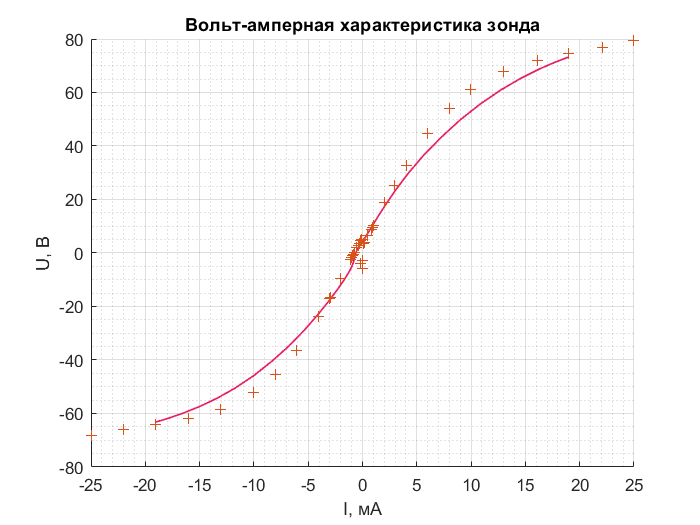

hold on
grid on
grid("minor")
V_3 = [ -24.96
-22
-19.04
-16.02
-13.05
-10
-10.08
-8.04
-6.12
-4.01
-3.01
-2.96
-2.05
0
-0.23
0
-1.1
-1
-0.9
-0.84
-0.74
-0.51
-0.39
0.1
-0.3
0.13
0.15
-0.15
-0.1
0.5
0.83
0.9
1
2.07
2.96
4.03
6.01
7.99
9.98
12.99
16.09
19
22.1
24.96

];
A_3 = [-68.07
-66.16
-64.17
-61.9
-58.4
-52.16
-52.09
-45.25
-36.4
-23.73
-17.04
-16.8
-9.7
-5.71
-4.06
-2.68
-2.57
-1.83
-1.06
-0.51
0.19
2
2.92
3.4
3.57
3.59
3.8
4.7
5.11
6.38
8.9
9.57
10.33
18.74
25.3
32.66
44.69
54.06
61.17
68.03
72.05
74.63
76.96
79.26

];
V_3_S = smoothdata(V_3,'gaussian',15);
A_3_S = smoothdata(A_3,'gaussian',15);
plot(V_3_S,A_3_S,"LineWidth",1,"Color",[0.9 0.108 0.38]);
scatter(V_3, A_3, "Marker","+","MarkerEdgeColor","flat");
title("Вольт-амперная характеристика зонда")
xlabel('I, мА')
ylabel('U, В')

xlim([-25.0 25.0])
ylim([-80 80])

## Clear temporary variables

clear opts